# MATLAB Deep Learning Toolbox

## MATLAB Deep Learning Toolbox

To use MATLAB's neural network software, we need to download the [Deep Learning Toolbox](https://www.mathworks.com/products/deep-learning.html#net). The documentation for the shallow neural network can be found on [this page](https://www.mathworks.com/help/deeplearning/getting-started-with-deep-learning-toolbox.html), and there is a really cool GUI tool that covers each step of the training process (which can be called using `nnstart,` and the documentation can found [here](https://www.mathworks.com/help/deeplearning/ref/nnstart.html)). However, we will go over training the same neural network we've trained in the last lecture using the command-line functions.

### Load the breast cancer image classification dataset

Let's load the breast cancer image classification dataset we've been using for the last two lectures. The MATLAB built-in functions process datasets where the features/target variables span the rows, while the observations span the columns.

clear all; rng(2);
load cancer_dataset.mat

% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(cancerInputs', cancerTargets(1, :)', ...
    trainingSize, randomstate);

% Standardize the dataset with mean = 0 and standard deviation = 1. 
mu = mean(Xtrain); sigma = std(Xtrain);
Xtrain = (Xtrain - mu) ./ sigma; 
Xtest  = (Xtest - mu)  ./ sigma; % Use the same mu and sigma -> assume same distribution

% Transpose all datasets
Xtrain = Xtrain'; Ytrain = Ytrain'; Xtest = Xtest'; Ytest = Ytest';

### Setting the shallow neural network architecture

Next, let's specify the neural network architecture for the shallow neural network, using the same architecture we've been using so far:

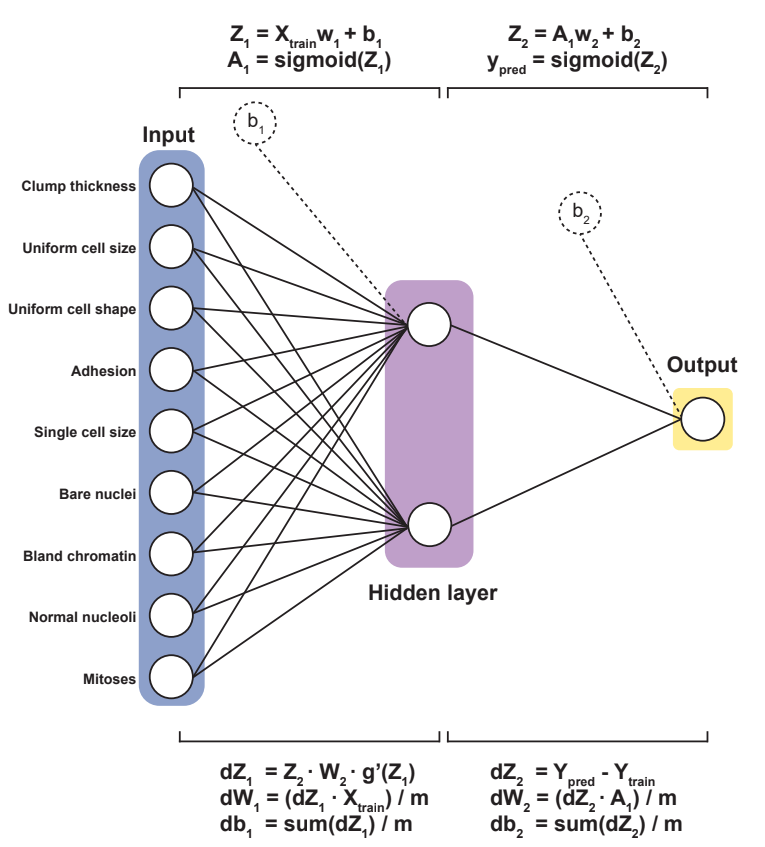

This can be done using the `feedforwardnet` function, which returns a structure consisting of the network values as fields. This function can be used for 1 or more hidden layers. To add more than 1 hidden layer, a vector of values representing the number of activation nodes in each layer can be supplied to construct the network.

Note that as a default, MATLAB uses the** Levenberg-Marquardt** algorithm, another optimization algorithm that tunes the model parameters to minimize the cost function. If you wanted to specify the optimization function as the gradient descent optimization algorithm, you can do so as the second argument in the `feedforwardnet` function. 

numOfActivationNodes = 2;         % 1 hidden layer with 2 activation nodes
optimizationFnc      = 'traingd'; % Gradient descent optimization algorithm
net                  = feedforwardnet(numOfActivationNodes, optimizationFnc)

net =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 2
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inputConne

### View the network structure with MATLAB's GUI

Let's view the network structure `net` using the `view` function, which utilizes MATLAB's GUI. 

view(net)

The popup screen should show you the following information:

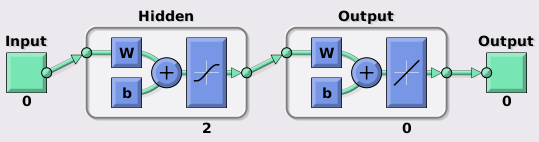

The numbers beneath each panel denotes the number of features (for the input/output) or the number of nodes in the network. Because we have not fitted the data using a training or testing set, the numbers below the input/output in the figure above are shown as 0. 

Note that this diagram is similar to the one we've been using to depict the network structure:

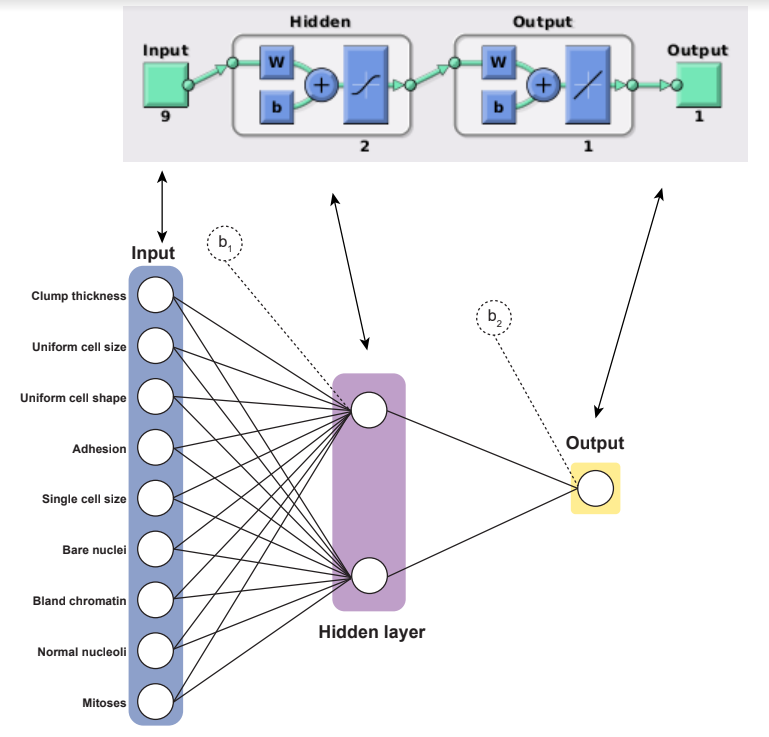

One main difference between the algorithm we wrote and MATLAB's algorithm is that MATLAB only performs a final linear combination from the hidden to the output layer, while we have been re-transforming the linear combination to probabilities using another `Sigmoid` activation function. 

### Setting up the network hyperparameters

Most of the hyperparameters can be modified by setting the fields in the `net` structure. We won't go over each individual hyperparameter here (the documentation to modify some training parameters can be found in this [link](https://www.mathworks.com/help/deeplearning/ref/traingda.html)), but we'll some of the relevant ones we discussed in the previous lectures.

#### Validation sets

To divide the data for training, validation, and testing, we can specifying some fields in the `net` structure we made from the `fitnet` function.

net.divideParam.trainRatio = 0.6; % Training set size
net.divideParam.testRatio  = 0.2; % Test set size
net.divideParam.valRatio   = 0.2; % Cross validation set size

During the training phase, if you input the entire dataset, it automatically splits the dataset into three groups: 60% training, 20% testing (holdout), and an additional 20% for cross validation accuracy determinination. 

#### Loss functions

By default, the loss function is specified as the mean squared error. We'll use the MATLAB default argument, but if we wanted to compute classification errors using the cross entropy loss function, we need to specify the `crossentropy` function using the following syntax:

#### Epochs

The number of epochs can be specified by setting the `net.trainParam.epochs` parameter. While MATLAB performs 1000 epochs by default, we'll set it to 10,000 epochs just to ensure we'll fully train the model. 

net.trainParam.epochs      = 10000;

Note that MATLAB automatically performs **early stopping - **it stops training the model when the model error increases during an epoch. This is a nice feature to implement that helps the model avoid overfitting. 

### Training the shallow neural network

Let's now train the shallow neural network using the `train` function, which will also show the MATLAB GUI while the model is training. An example of the GUI is shown below.

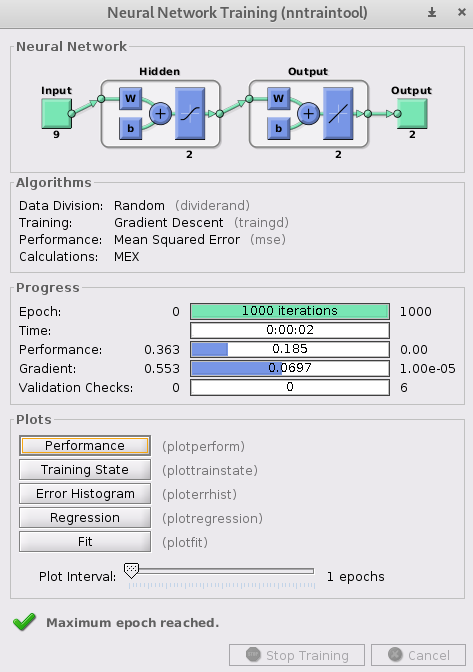

`train` takes in the network architecture we specified (`net)`, the `input` data, and the target labels `outputs`, and outputs the trained neural network (`trainedNet)`, as well as the computed metrics (`trainingRecord)`. 

[trainedNet, trainingRecord] = train(net, Xtrain, Ytrain)

trainedNet =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 23
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      in

trainingRecord = struct with fields:
        trainFcn: 'traingd'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1×335 double]
          valInd: [1×112 double]
         testInd: [1×112 double]
            stop: 'Maximum epoch reached.'
      num_epochs: 10000
       trainMask: {[1×559 double]}
         valMask: {[1×559 double]}
        testMask: {[1×559 double]}
      best_epoch: 10000
            goal: 0
          states: {1×7 cell}
           epoch: [1×10001 double]
            time: [1×10001 double]
            perf: [1×10001 double]
           vperf: [1×10001 double]
           tperf: [1×10001 double]
        gradient: [1×10001 double]
        val_fail: [1×10001 double]
       best_perf: 0.0225
      best_vperf: 0.0503
      best_tperf: 0.0269


### Computing model predictions and evaluating model performance

First, we'll compute our predictions using the test dataset. The trained neural network `trainedNet` also acts as function to compute predictions. We can use the following syntax to compute the predicted Y values from the test set.

ypred = trainedNet(Xtest)

ypred =    -0.0992    0.0179    1.0105    0.3424    0.9180    1.0113    0.2061    0.0652    1.0113    1.0152    0.0065    0.0188    1.0073    0.0097    0.3791    0.9813    1.0125    0.0470   -0.0169    1.0152   -0.0345    0.0415    0.0387    0.9655    0.9908    0.9455    0.0925    0.9672    0.0022    0.0545    0.2487    0.9767    0.0020    0.9983    0.9659    0.0273   -0.1891    1.0109    0.9983    1.0125    0.0514    1.0080    0.9510    1.0073    1.0080    1.0031    0.8407    0.2494    1.0073    0.0340


From here we can use the methods we described previously to evaluate the model. To evaluate the model's performance (mean-squared error), we can use the built-in `perform` function, which has the following syntax:

error = perform(trainedNet, Ytest, ypred)

error = 0.0245

### Plotting model metrics 

#### Cost Curves

We can plot the cost curves we've generated previously using the `plotperf` function. Note that the error is in log-scale, unlike the plots we have computed previously. Additionally, it plots the training error, test error, and validation error as separate cost curves.

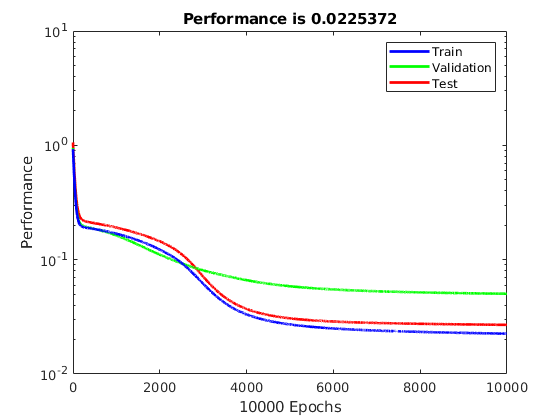

plotperf(trainingRecord)

### Confusion matricies

Now plot a confusion matrix of the model holdout using the `confusionmat` and the `confusionchart` functions..

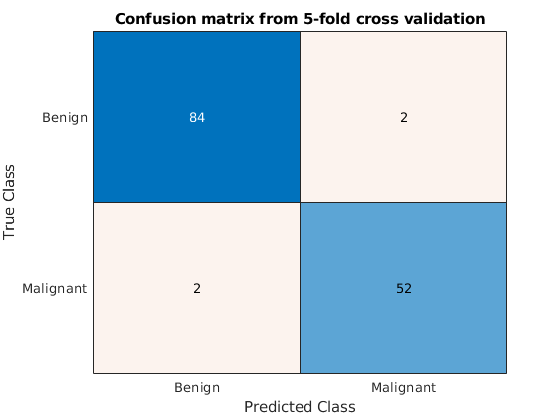

cm = confusionmat(round(ypred), Ytest);
figure; labels = {'Malignant', 'Benign'};
confusionchart(cm, labels)
title('Confusion matrix from 5-fold cross validation');

TP  = cm(1, 1); FP = cm(1, 2); FN = cm(2, 1); TN  = cm(2, 2);
malignant_precision = (TP) / (TP + FP)

malignant_precision = 0.9630

malignant_recall    = (TP) / (TP + FN)

malignant_recall = 0.9630

benign_precision    = (TN) / (TN + FP)

benign_precision = 0.9767

benign_recall       = (TN) / (TN + FN)

benign_recall = 0.9767

average_accuracy    = sum(diag(cm)) / sum(cm, 'all')

average_accuracy = 0.9714

## Deep feed-forward neural networks and deep learning

Up until this point, we have only been dealing with a single hidden layer:

What if we wanted to extend our neural network's capacity to handle $L$hidden layers to train a more non-linear model? We can generalize the approach we have used to construct the shallow neural network using the generalized forward and backward propagation algorithm, shown below. 

#### The general forward propagation algorithm

$Z^{\left\lbrack L\right\rbrack } =A^{\left\lbrack L-1\right\rbrack } w^{\left\lbrack L\right\rbrack } +{b\;}^{\left\lbrack L\right\rbrack }$. Note that $A^{\left\lbrack 1\right\rbrack } =X$.

$A^{\left\lbrack L\right\rbrack } =g^{\left\lbrack L\right\rbrack } \left(Z^{\left\lbrack L\right\rbrack } \right)$, where $g^{\left\lbrack L\right\rbrack }$ is a non-linear function of our choosing at an $L^{\textrm{th}}$ layer.

#### The general backward propagation algorithm

${\textrm{dZ}}^{\left\lbrack L\right\rbrack } ={\textrm{dA}}^{\left\lbrack L\right\rbrack } \cdot$$g^{\prime \left\lbrack L\right\rbrack } \left(Z^{\left\lbrack L\right\rbrack } \right)$, where ${\textrm{dA}}^{\left\lbrack \textrm{end}\right\rbrack } =Y_{\textrm{train}} -Y_{\textrm{pred}}$ and $g^{\prime \left\lbrack L\right\rbrack }$ is the derivative term for the activation function at layer $L$.


$${\textrm{dA}}^{\left\lbrack L-1\right\rbrack } =W^{\left\lbrack L\right\rbrack } {\textrm{dZ}}^{\left\lbrack L\right\rbrack }$$



$${\textrm{dW}}^{\left\lbrack L\right\rbrack } =\frac{1}{m}\left({{\textrm{dZ}}^{\left\lbrack L\right\rbrack } A}^{\left\lbrack L-1\right\rbrack } \right);$$

$${\textrm{db}}^{\left\lbrack L\right\rbrack } =\frac{1}{m}\left({\textrm{dZ}}^{\left\lbrack L\right\rbrack } \right)$$


### Deep neural networks from the Deep Learning Toolbox

MATLAB has made it easy to construct deep neural networks by simply using the `trainNetwork` function. It takes in the datasets $X_{\textrm{train}}$ and $Y_{\textrm{train}}$, the network architecture as the third argument, and the hyperparameter specifications in the 4th argument. We'll use the breast cancer imaging dataset to train and test this deep neural network.

clear all; rng(2);
load cancer_dataset.mat

% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(cancerInputs', cancerTargets(1, :)', ...
    trainingSize, randomstate);

% Standardize the dataset with mean = 0 and standard deviation = 1. 
mu = mean(Xtrain); sigma = std(Xtrain);
Xtrain = (Xtrain - mu) ./ sigma; 
Xtest  = (Xtest - mu)  ./ sigma; % Use the same mu and sigma -> assume same distribution

% Transpose all datasets
Xtrain = Xtrain'; Ytrain = Ytrain'; Xtest = Xtest'; Ytest = Ytest';

For a classification problem, the labels need to be transformed to a categorical data type to use MATLAB's `trainNetwork` function:

Ytrain = categorical(Ytrain); Ytest = categorical(Ytest);

Now, we need to specify the neural network architecture. We will store the network as an array called `layers`. We'll be constructing a deep neural network that has the following structure:

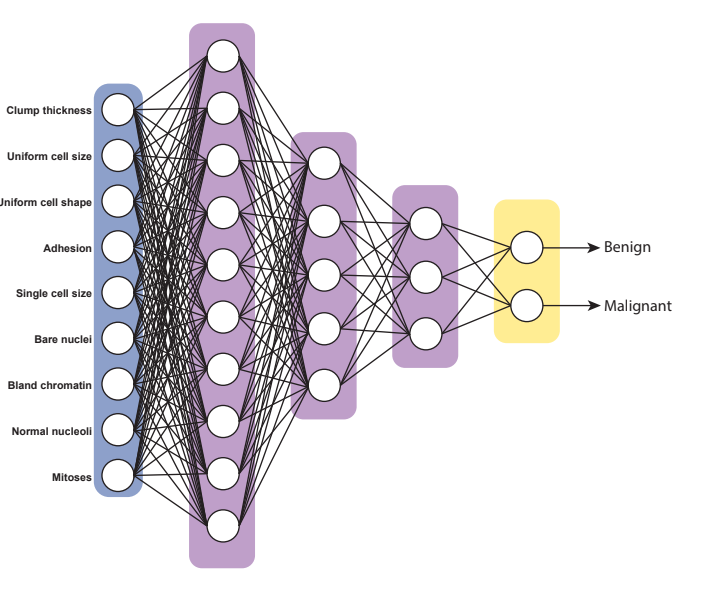

**There are 4 components we need to specify in the **`layer`** array:**

- **Input data layer**: the specific function differs on the data type inputed. For numerical data, the `sequenceInputLayer` is the appropriate function, which needs the number of features as the parameter.

- **Hidden layer architecture**: the specific architecture needed to design a feedforward neural network is the `fullyConnectedLayer`, which needs the number of activation nodes as the first parameter. The `WeightsInitializer` and `BiasInitializer` parameters tell the function how to initialize the parameters, using small random numbers from a normal distribution.

- **Activation function**: Between each `fullyConnectedLayer` is the activation function. The `softmaxLayer` is the activation function we will use.

- **Classification layer** (optional): The `classificationLayer` transforms the values to their predicted labels.

% Specify neural network architecture
layers = [...
    
    sequenceInputLayer(size(Xtrain, 1)), ...            % Input data layer

    fullyConnectedLayer(10, ...                         % Hidden layer 1 with 10 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                                   % Activation function 1
    
    fullyConnectedLayer(5, ...                         % Hidden layer 2 with 5 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                                   % Activation function 2
    
    fullyConnectedLayer(3, ...                         % Hidden layer 3 with 3 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                                   % Activation function 3
    
    fullyConnectedLayer(2, ...                          % Output layer with 2 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                                   % Transform to probabilities
    
    classificationLayer ...                             % Label encode
]

layers =   10x1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 9 dimensions
     2   ''   Fully Connected         10 fully connected layer
     3   ''   Softmax                 softmax
     4   ''   Fully Connected         5 fully connected layer
     5   ''   Softmax                 softmax
     6   ''   Fully Connected         3 fully connected layer
     7   ''   Softmax                 softmax
     8   ''   Fully Connected         2 fully connected layer
     9   ''   Softmax                 softmax
    10   ''   Classification Output   crossentropyex

Next, we have to specify the model hyperparameters. The `trainingOptions` function creates a model object that lets you feed in the hyperparameters into the neural network function. The specific arguments we will use are shown below.

% Spcify hyperparameters for neural network
options = trainingOptions(...
    'adam', ...                                   % Adam optimization
    'InitialLearnRate', 0.01, ...                 % Set the initial learning rate to 0.01 
    'MaxEpochs', 2000, ...                        % Maximum number of epochs to train algorithm
    'ValidationData', {Xtest, Ytest}, ...         % Dataset to use as the validation set
    'ValidationFrequency', 30, ...                % Frequency to validate the network at regular intervals
    'Verbose', true, ...                          % Outputs information about training 
    'Shuffle', 'every-epoch', ...                 % Data shuffling for every epoch
    'Plots', 'training-progress' ...              % Show plots for every epoch
);                

Finally, let's train the neural network using the `trainNetwork` function, which allows us to train other deep neural network architectures. For more information on other neural networks you can train using this function, you can [read the documentation](https://www.mathworks.com/help/deeplearning/ref/trainnetwork.html).

Training on single GPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:03 |       66.55% |       61.43% |       0.6895 |       0.6865 |          0.0100 |


|      30 |          30 |       00:00:04 |       66.55% |       61.43% |       0.6386 |       0.6796 |          0.0100 |


|      50 |          50 |       00:00:04 |       66.55% |              |       0.6313 |              |          0.0100 |


|      60 |          60 |       00:00:05 |       66.55% |       61.43% |       0.6054 |       0.6338 |          0.0100 |


|      90 |          90 |       00:00:05 |       97.50% |       97.14% |       0.3501 |       0.3557 |          0.0100 |


|     100 |         100 |       00:00:05 |       97.67% |              |       0.2701 |              |          0.0100 |


|     120 |         120 |       00:00:06 |       98.03% |       97.86% |       0.1751 |       0.1795 |          0.0100 |


|     150 |         150 |       00:00:06 |       98.03% |       97.86% |       0.1238 |       0.1285 |          0.0100 |


|     180 |         180 |       00:00:07 |       98.03% |       97.86% |       0.1059 |       0.1105 |          0.0100 |


|     200 |         200 |       00:00:07 |       98.03% |              |       0.0997 |              |          0.0100 |


|     210 |         210 |       00:00:07 |       98.03% |       97.86% |       0.0975 |       0.1018 |          0.0100 |


|     240 |         240 |       00:00:08 |       98.03% |       97.86% |       0.0928 |       0.0968 |          0.0100 |


|     250 |         250 |       00:00:08 |       98.03% |              |       0.0917 |              |          0.0100 |


|     270 |         270 |       00:00:08 |       98.03% |       97.86% |       0.0900 |       0.0936 |          0.0100 |


|     300 |         300 |       00:00:09 |       98.03% |       97.86% |       0.0881 |       0.0915 |          0.0100 |


|     330 |         330 |       00:00:10 |       98.03% |       97.86% |       0.0868 |       0.0900 |          0.0100 |


|     350 |         350 |       00:00:10 |       98.03% |              |       0.0862 |              |          0.0100 |


|     360 |         360 |       00:00:10 |       98.03% |       97.86% |       0.0859 |       0.0888 |          0.0100 |


|     390 |         390 |       00:00:11 |       98.03% |       97.86% |       0.0852 |       0.0879 |          0.0100 |


|     400 |         400 |       00:00:11 |       98.03% |              |       0.0850 |              |          0.0100 |


|     420 |         420 |       00:00:11 |       98.03% |       97.86% |       0.0847 |       0.0871 |          0.0100 |


|     450 |         450 |       00:00:12 |       98.03% |       97.86% |       0.0844 |       0.0864 |          0.0100 |


|     480 |         480 |       00:00:12 |       98.03% |       97.86% |       0.0841 |       0.0857 |          0.0100 |


|     500 |         500 |       00:00:13 |       98.03% |              |       0.0839 |              |          0.0100 |


|     510 |         510 |       00:00:13 |       98.03% |       97.86% |       0.0838 |       0.0849 |          0.0100 |


|     540 |         540 |       00:00:13 |       98.03% |       97.86% |       0.0836 |       0.0839 |          0.0100 |


|     550 |         550 |       00:00:13 |       98.03% |              |       0.0835 |              |          0.0100 |


|     570 |         570 |       00:00:14 |       98.03% |       97.86% |       0.0833 |       0.0817 |          0.0100 |


|     600 |         600 |       00:00:14 |       97.67% |       97.86% |       0.0667 |       0.0947 |          0.0100 |


|     630 |         630 |       00:00:15 |       98.75% |       97.86% |       0.0461 |       0.0877 |          0.0100 |


|     650 |         650 |       00:00:15 |       99.64% |              |       0.0323 |              |          0.0100 |


|     660 |         660 |       00:00:15 |       99.64% |       97.86% |       0.0303 |       0.0965 |          0.0100 |


|     690 |         690 |       00:00:16 |       99.64% |       97.86% |       0.0279 |       0.1018 |          0.0100 |


|     700 |         700 |       00:00:16 |       99.64% |              |       0.0274 |              |          0.0100 |


|     720 |         720 |       00:00:16 |       99.64% |       97.86% |       0.0267 |       0.1044 |          0.0100 |


|     750 |         750 |       00:00:17 |       99.64% |       97.86% |       0.0257 |       0.1070 |          0.0100 |


|     780 |         780 |       00:00:17 |       99.64% |       97.86% |       0.0252 |       0.1115 |          0.0100 |


|     800 |         800 |       00:00:18 |       99.64% |              |       0.0250 |              |          0.0100 |


|     810 |         810 |       00:00:18 |       99.64% |       97.86% |       0.0249 |       0.1148 |          0.0100 |


|     840 |         840 |       00:00:19 |       99.64% |       97.86% |       0.0247 |       0.1171 |          0.0100 |


|     850 |         850 |       00:00:19 |       99.64% |              |       0.0246 |              |          0.0100 |


|     870 |         870 |       00:00:19 |       99.64% |       97.14% |       0.0245 |       0.1189 |          0.0100 |


|     900 |         900 |       00:00:20 |       99.64% |       97.14% |       0.0243 |       0.1204 |          0.0100 |


|     930 |         930 |       00:00:20 |       99.64% |       97.14% |       0.0242 |       0.1216 |          0.0100 |


|     950 |         950 |       00:00:21 |       99.64% |              |       0.0241 |              |          0.0100 |


|     960 |         960 |       00:00:21 |       99.64% |       97.14% |       0.0241 |       0.1227 |          0.0100 |


|     990 |         990 |       00:00:21 |       99.64% |       97.14% |       0.0240 |       0.1237 |          0.0100 |


|    1000 |        1000 |       00:00:22 |       99.64% |              |       0.0240 |              |          0.0100 |


|    1020 |        1020 |       00:00:22 |       99.64% |       97.14% |       0.0239 |       0.1246 |          0.0100 |


|    1050 |        1050 |       00:00:23 |       99.64% |       97.14% |       0.0239 |       0.1253 |          0.0100 |


|    1080 |        1080 |       00:00:23 |       99.64% |       97.14% |       0.0238 |       0.1260 |          0.0100 |


|    1100 |        1100 |       00:00:24 |       99.64% |              |       0.0238 |              |          0.0100 |


|    1110 |        1110 |       00:00:24 |       99.64% |       97.14% |       0.0238 |       0.1266 |          0.0100 |


|    1140 |        1140 |       00:00:24 |       99.64% |       97.14% |       0.0237 |       0.1272 |          0.0100 |


|    1150 |        1150 |       00:00:24 |       99.64% |              |       0.0237 |              |          0.0100 |


|    1170 |        1170 |       00:00:25 |       99.64% |       97.14% |       0.0237 |       0.1277 |          0.0100 |


|    1200 |        1200 |       00:00:25 |       99.64% |       97.14% |       0.0237 |       0.1281 |          0.0100 |


|    1230 |        1230 |       00:00:26 |       99.64% |       97.14% |       0.0237 |       0.1285 |          0.0100 |


|    1250 |        1250 |       00:00:26 |       99.64% |              |       0.0236 |              |          0.0100 |


|    1260 |        1260 |       00:00:26 |       99.64% |       97.14% |       0.0236 |       0.1289 |          0.0100 |


|    1290 |        1290 |       00:00:27 |       99.64% |       97.14% |       0.0236 |       0.1292 |          0.0100 |


|    1300 |        1300 |       00:00:27 |       99.64% |              |       0.0236 |              |          0.0100 |


|    1320 |        1320 |       00:00:27 |       99.64% |       97.14% |       0.0236 |       0.1295 |          0.0100 |


|    1350 |        1350 |       00:00:28 |       99.64% |       97.14% |       0.0236 |       0.1298 |          0.0100 |


|    1380 |        1380 |       00:00:28 |       99.64% |       97.14% |       0.0236 |       0.1300 |          0.0100 |


|    1400 |        1400 |       00:00:29 |       99.64% |              |       0.0236 |              |          0.0100 |


|    1410 |        1410 |       00:00:29 |       99.64% |       97.14% |       0.0236 |       0.1302 |          0.0100 |


|    1440 |        1440 |       00:00:30 |       99.64% |       97.14% |       0.0236 |       0.1304 |          0.0100 |


|    1450 |        1450 |       00:00:30 |       99.64% |              |       0.0236 |              |          0.0100 |


|    1470 |        1470 |       00:00:30 |       99.64% |       97.14% |       0.0236 |       0.1306 |          0.0100 |


|    1500 |        1500 |       00:00:31 |       99.64% |       97.14% |       0.0236 |       0.1308 |          0.0100 |


|    1530 |        1530 |       00:00:31 |       99.64% |       97.14% |       0.0235 |       0.1309 |          0.0100 |


|    1550 |        1550 |       00:00:31 |       99.64% |              |       0.0235 |              |          0.0100 |


|    1560 |        1560 |       00:00:32 |       99.64% |       97.14% |       0.0235 |       0.1311 |          0.0100 |


|    1590 |        1590 |       00:00:32 |       99.64% |       97.14% |       0.0235 |       0.1312 |          0.0100 |


|    1600 |        1600 |       00:00:32 |       99.64% |              |       0.0235 |              |          0.0100 |


|    1620 |        1620 |       00:00:33 |       99.64% |       97.14% |       0.0235 |       0.1314 |          0.0100 |


|    1650 |        1650 |       00:00:33 |       99.64% |       97.14% |       0.0235 |       0.1316 |          0.0100 |


|    1680 |        1680 |       00:00:34 |       99.64% |       97.14% |       0.0235 |       0.1319 |          0.0100 |


|    1700 |        1700 |       00:00:34 |       99.64% |              |       0.0235 |              |          0.0100 |


|    1710 |        1710 |       00:00:34 |       99.64% |       97.14% |       0.0235 |       0.1327 |          0.0100 |


|    1740 |        1740 |       00:00:35 |       99.64% |       97.14% |       0.0202 |       0.1430 |          0.0100 |


|    1750 |        1750 |       00:00:35 |       99.46% |              |       0.0176 |              |          0.0100 |


|    1770 |        1770 |       00:00:35 |       99.64% |       97.14% |       0.0158 |       0.1435 |          0.0100 |


|    1800 |        1800 |       00:00:36 |       99.82% |       97.14% |       0.0126 |       0.1382 |          0.0100 |


|    1830 |        1830 |       00:00:36 |       99.82% |       97.86% |       0.0124 |       0.1314 |          0.0100 |


|    1850 |        1850 |       00:00:36 |       99.82% |              |       0.0123 |              |          0.0100 |


|    1860 |        1860 |       00:00:37 |       99.82% |       97.86% |       0.0122 |       0.1330 |          0.0100 |


|    1890 |        1890 |       00:00:37 |       99.82% |       97.86% |       0.0121 |       0.1346 |          0.0100 |


|    1900 |        1900 |       00:00:37 |       99.82% |              |       0.0121 |              |          0.0100 |


|    1920 |        1920 |       00:00:38 |       99.82% |       97.86% |       0.0121 |       0.1362 |          0.0100 |


|    1950 |        1950 |       00:00:38 |       99.82% |       97.86% |       0.0120 |       0.1377 |          0.0100 |


|    1980 |        1980 |       00:00:39 |       99.82% |       97.86% |       0.0119 |       0.1392 |          0.0100 |


|    2000 |        2000 |       00:00:39 |       99.82% |       97.86% |       0.0119 |       0.1402 |          0.0100 |


|======================================================================================================================|


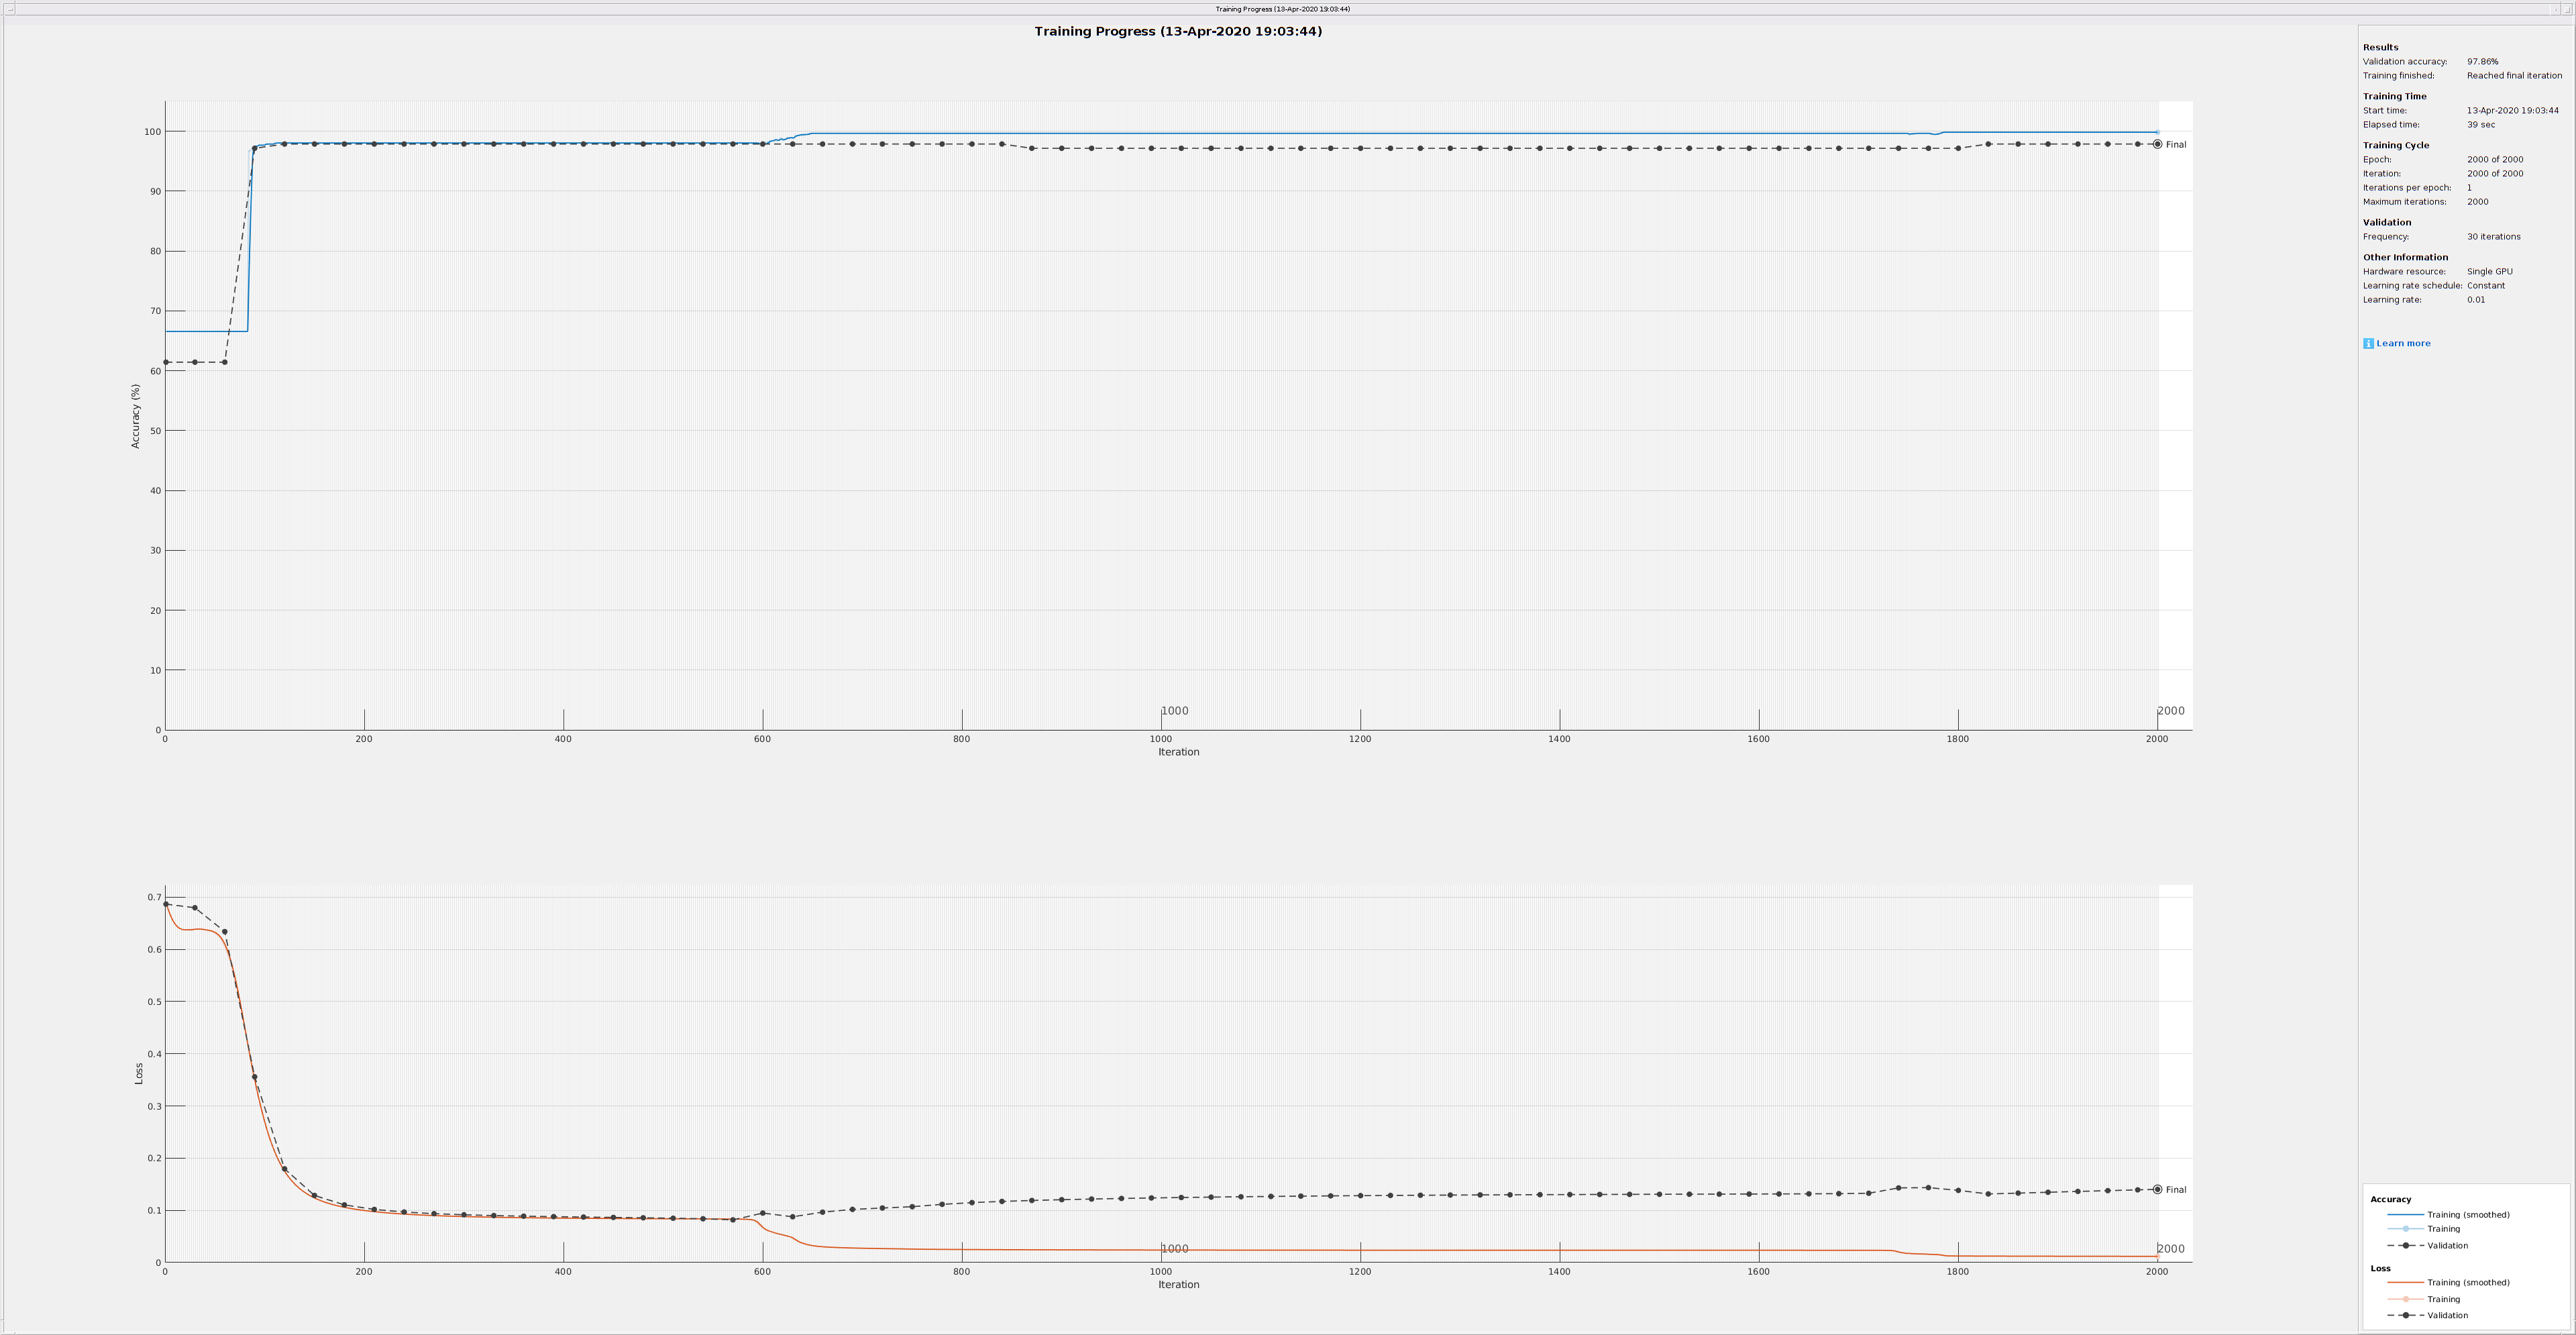

dnn =   SeriesNetwork with properties:

         Layers: [10×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'classoutput'}


trainingInfo = struct with fields:
               TrainingLoss: [1×2000 double]
           TrainingAccuracy: [1×2000 double]
             ValidationLoss: [1×2000 double]
         ValidationAccuracy: [1×2000 double]
              BaseLearnRate: [1×2000 double]
        FinalValidationLoss: 0.1402
    FinalValidationAccuracy: 97.8571


[dnn, trainingInfo] = trainNetwork(Xtrain, Ytrain, layers, options)

The plot shown in the popup shows the accuracy and cost of training the neural network as a function the number of epochs, and shows the generation of the accuracy / cost curves in real time. 

To make predictions using the deep neural network model, we can use the built-in `predict` function, which returns the class probabilites.

ypred_dnn = predict(dnn, Xtest)

ypred_dnn = 2×140 single matrix
    0.9933    0.9933    0.0010    0.0011    0.0010    0.0010    0.9890    0.9933    0.0010    0.0010    0.9933    0.9933    0.0010    0.9933    0.9933    0.0010    0.0010    0.9933    0.9933    0.0010    0.9933    0.9933    0.9933    0.0010    0.0010    0.0010    0.9933    0.0010    0.9933    0.9933    0.0011    0.0010    0.9933    0.0010    0.0010    0.9933    0.9933    0.0010    0.0010    0.0010    0.9933    0.0010    0.0010    0.0010    0.0010    0.0010    0.9895    0.9933    0.0010    0.9933
    0.0067    0.0067    0.9990    0.9989    0.9990    0.9990    0.0110    0.0067    0.9990    0.9990    0.0067    0.0067    0.9990    0.0067    0.0067    0.9990    0.9990    0.0067    0.0067    0.9990    0.0067    0.0067    0.0067    0.9990    0.9990    0.9990    0.0067    0.9990    0.0067    0.0067    0.9989    0.9990    0.0067    0.9990    0.9990    0.0067    0.0067    0.9990    0.9990    0.9990    0.0067    0.9990    0.9990    0.9990    0.9990    0.9990    0.0

Let's plot the final confusion matrix for the deep feedforward neural network:

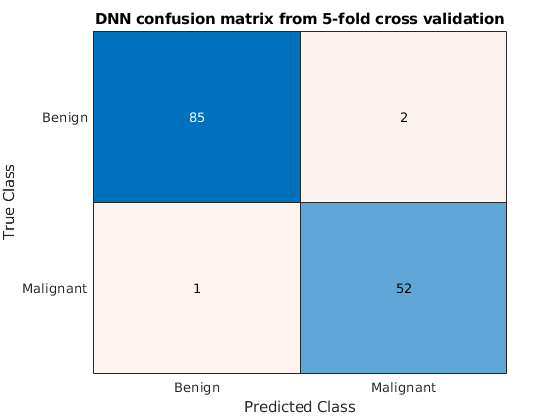

cm = confusionmat(categorical(round(ypred_dnn(2, :))), Ytest);
figure; labels = {'Malignant', 'Benign'};
confusionchart(cm, labels)
title('DNN confusion matrix from 5-fold cross validation');

TP  = cm(1, 1); FP = cm(1, 2); FN = cm(2, 1); TN  = cm(2, 2);
malignant_precision = (TP) / (TP + FP)

malignant_precision = 0.9811

malignant_recall    = (TP) / (TP + FN)

malignant_recall = 0.9630

benign_precision    = (TN) / (TN + FP)

benign_precision = 0.9884

benign_recall       = (TN) / (TN + FN)

benign_recall = 0.9770

average_accuracy    = sum(diag(cm)) / sum(cm, 'all')

average_accuracy = 0.9786

## Summary

We've learned MATLAB's functions for training neural networks, and applied them to k-class classification problems. Finally, we covered how to use MATLAB's deep neural network toolbox to train a deep neural network. An additional lecture (`imaging.mlx)` has been provided to show how deep neural networks can be used in regression problems to analyze tumor imaging data.

In the final part of this lecture series, we'll discuss potential difficulties in training neural networks, strategies to address these potential difficulties, and how to optimize the training phase using parallel computing and hyperparameter optimization. 

### Built-in MATLAB functions

`feedforwardnet:           `Initializes a feedforward neural network structure.

`plotperf:                 `Plots the cost curves from training a neural network.

`train:                    `Trains a shallow / feedforward neural network object.

`classificationLayer:      `Computes the cross entropy loss for multi-class classification problems.

`softmaxLayer:            `  Creates a softmax activation function layer for binary- and multi-classification problems.

`sequenceInputLayer:       `Stores the input dataset $X_{\textrm{train}}$ as a MATLAB object for the `trainNetwork` function.

`fullyConnectedLayer:      `Creates a single hidden layer object for the` trainNetwork `function.

`trainingOptions:          `Creates an object used in the `trainNetwork` function that specifies the neural network hyperparameters.

`trainNetwork:             `Trains (among other network structures) a deep feedforward neural network.

`confusionmat:             `Automatically computes a confusion matrix for each class.

`confusionchart`:                         Plots the confusion matrix from `confusionmat.`

### Custom MATLAB functions

`trainTestSplit:           `Splits an input ($X$) and output ($Y$) dataset into a training $\left(X_{\textrm{train}} {,\;Y}_{\textrm{train}} \right)$ and testing $\left(X_{\textrm{test}} {,\;Y}_{\textrm{test}} \right)$ dataset